# MidTerm

# Name - Vinay Patil

# Net Id - vpatil3

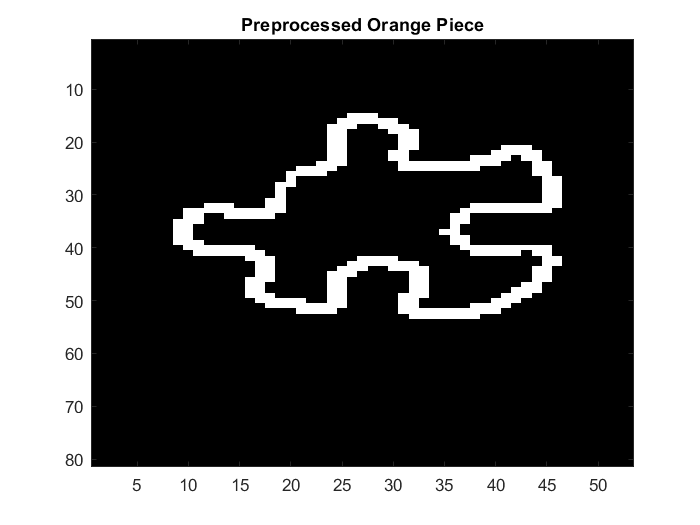

%Preprocessing steps for orange_piece.jpg

%Converting to double to maintain precision
orangePiece = double(imread("orange_piece.jpg"));

%Resize orangePiece to lower the resolution by a factor of 5
newOrangePieceRows = ceil(size(orangePiece,1)/5);
newOrangePieceCols = ceil(size(orangePiece,2)/5);
orangePiece = imresize(orangePiece,[newOrangePieceRows newOrangePieceCols]);

%Changing the RGB image to grayscale
orangePiece = 0.2989*orangePiece(:,:,1)+0.5870*orangePiece(:,:,2)+0.1140*orangePiece(:,:,3);

%Applying median filter to removing noise from the data
orangePieceGray = medfilt2(orangePiece);

%Using sobel to detecting edges of the image
ksx = reshape([-1 -2 -1 0 0 0 1 2 1], 3, 3 );
ksy = ksx';
gx = conv2(orangePieceGray, ksx, 'same');
gy = conv2(orangePieceGray, ksy, 'same');
orangePiece = sqrt(gx.^2 + gy.^2);

%Binarizing the image
orangePiece = orangePiece>330;

%Displaying the preprocessed Image
colormap('gray');
imagesc(orangePiece);
title("Preprocessed Orange Piece");

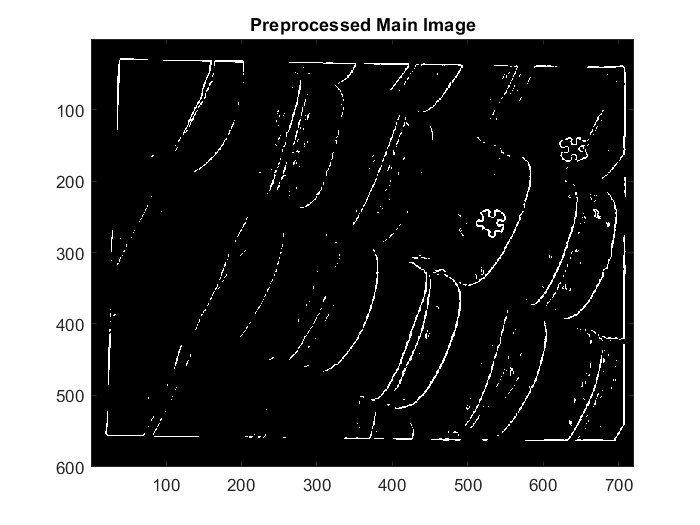

%Finding the coordinate centers, to aid in the construction of R-Table for the generalized hough process
[x_coord,y_coord] = find(orangePiece >0);
x_c = round(mean(x_coord));
y_c = round(mean(y_coord));

%Finding phi angle for all the edge points of the orange piece 
dir_grad_piece = atan2(gy,gx);
dir_grad_piece(orangePiece==0) = 0;
dir_grad_piece = round(dir_grad_piece*180/pi);

%Getting unique angles and ignoring non-edge angles i.e 0
unique_angles = unique(dir_grad_piece);
unique_angles = unique_angles(unique_angles~=0);

%Constructing R-Table for the orange piece
R_Table = struct;
count = 1;
for phi_degree=unique_angles'
    [x,y] = find(dir_grad_piece==phi_degree);
    x_prime = x_c - x;
    y_prime = y_c - y;
    
    %Calculating Length r
    r = sqrt(x_prime.^2 + y_prime.^2);
    
    %Calculating alpha in radians
    alpha_rad = atan2(y_prime,x_prime);
    
    %Grouping alpha and r
    R_Table(count).phi = phi_degree;
    R_Table(count).alpha = round(alpha_rad*180/pi)';
    R_Table(count).length = r';
    count = count + 1;
end

%Preprocessing steps for the main image

%Converting to double to maintain precision
main = double(imread("main.jpg"));

%Resize main image to lower the resolution by a factor of 5
newMainRows = ceil(size(main,1)/5);
newMainCols = ceil(size(main,2)/5);
main = imresize(main,[newMainRows newMainCols]);

%Changing the RGB image to grayscale
main = 0.2989*main(:,:,1)+0.5870*main(:,:,2)+0.1140*main(:,:,3);

%Applying median filter to removing noise from the data
mainGray = medfilt2(main);

%Using sobel to detecting edges of the image
gx = conv2(mainGray, ksx, 'same');
gy = conv2(mainGray, ksy, 'same');
main = sqrt(gx.^2 + gy.^2);

%Binarizing the image
main = main>250;

%Displaying the preprocessed Image
imagesc(main);
title("Preprocessed Main Image");

**1. Generalized Hough Transform**

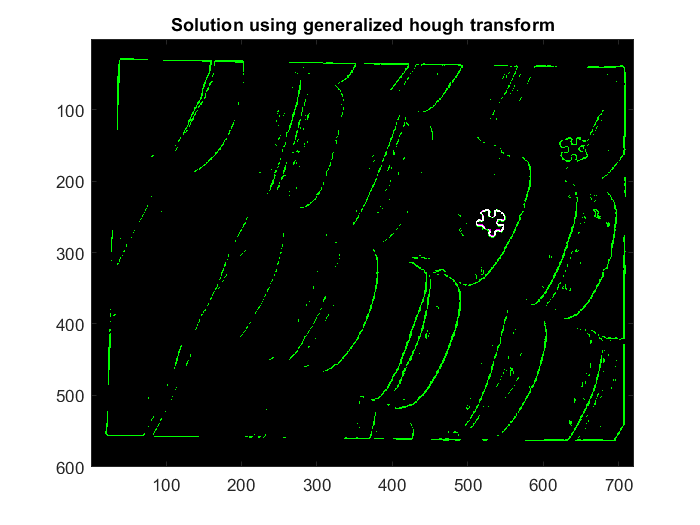

%Finding phi angle for all the edge points of the main 
dir_grad_main = atan2(gy,gx);
dir_grad_main(main==0) = 0;
dir_grad_main = round(dir_grad_main*180/pi);

%Getting unique angles and ignoring non-edge angles i.e 0
unique_angles = unique(dir_grad_main);
unique_angles = unique_angles(unique_angles~=0);

%Building accumulation matrix - Will be 8 in number, as there are 8 possible R-Tables 
rows = size(main,1);
cols = size(main,2);
no_of_rotations = 360/45;
acc_matrix = zeros(rows,cols,no_of_rotations);

%Initializing new table to R_Table as it remains same for the 0 degree rotation
R_Table_New = R_Table;

for rot=0:no_of_rotations-1
    
    %Rotating the R_Table for 45,90,...,315 degrees. The function is at the end of the script.
    if(rot>0)
        R_Table_New = rotatePhi(R_Table,rot);
    end
    
    %Iterating over all the unique angles
    for phi_degree=unique_angles'
        [x,y] = find(dir_grad_main==phi_degree);
        
        %Getting the match
        matchedLogical = [R_Table_New.phi]==phi_degree;
        
        %Checking if there is a match, if not then continue to the next phi angle
        if sum(matchedLogical)==1
            match = R_Table_New(matchedLogical);
            
            % The length vector will also be of same size, can consider either here
            nums = length(match.alpha); 
            
            for i=1:nums
                x_candidate = round(x + match.length(i)*cos(match.alpha(i)*pi/180));
                y_candidate = round(y + match.length(i)*sin(match.alpha(i)*pi/180));
                
                %Filtering coordintes that won't fall within the accumulator matrix space
                coord_x = x_candidate<=rows & x_candidate>0;
                coord_y = y_candidate<=cols & y_candidate>0;
                valids = coord_x & coord_y;
                x_candidate = x_candidate(valids);
                y_candidate = y_candidate(valids);
                
                %count contains the total no of valid pairs available 
                count = sum(valids);
                
                for j=1:count
                    acc_matrix(x_candidate(j),y_candidate(j),rot+1) = acc_matrix(x_candidate(j),y_candidate(j),rot+1) + 1;
                end
            end
        end
    end
end

%Finding optimal accumulator matrix
max_val = 0;
x_cen = 0;
y_cen = 0;
rot_index = 0;

for h=1:no_of_rotations
    acc = acc_matrix(:,:,h);
    
    %Replacing raw values with percentages
    acc =  acc./sum(acc(:));
    
    %Getting the max value and its linear index
    [M,X] = max(acc(:));
    
    %Comparing the value with the current maximum
    if(M>max_val)
        max_val = M;
        [x_cen,y_cen] = ind2sub(size(acc),X);
        rot_index = h;
    end
end

%Generating the shape with the optimal R_Table
generated_shape = zeros(rows,cols);
table = rotatePhi(R_Table,rot_index-1);

for k=1:length(table)
    nums = length(table(k).alpha);
    for i=1:nums
        xloop = round(x_cen-(table(k).length(i)*cos(table(k).alpha(i)*pi/180)));
        yloop = round(y_cen-(table(k).length(i)*sin(table(k).alpha(i)*pi/180)));
        if xloop>0 && yloop>0 && xloop<=rows && yloop<=cols
            generated_shape(xloop,yloop) = 1;
        end
    end
end

%Combining the preprocessed main image with the generated shape
fused_img = imfuse(main, generated_shape);
imagesc(fused_img);
title('Solution using generalized hough transform');
colormap('gray');

**2. Image Registration**

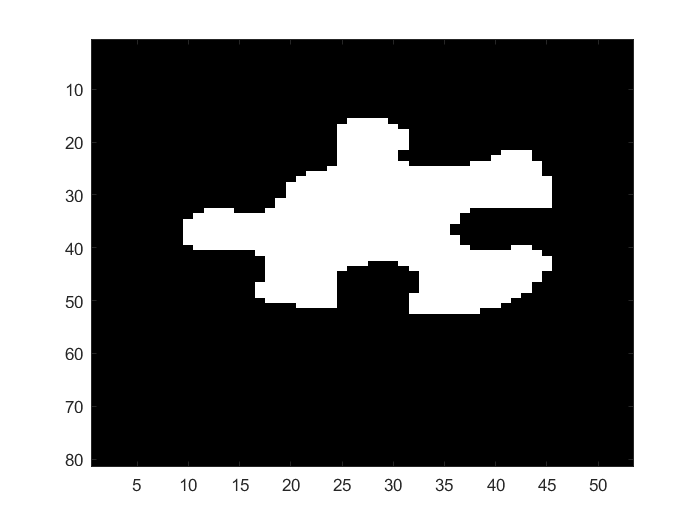

%Re-thresholding orange piece to help in image registration process 
orangePiece = orangePieceGray > 100;
imagesc(orangePiece);

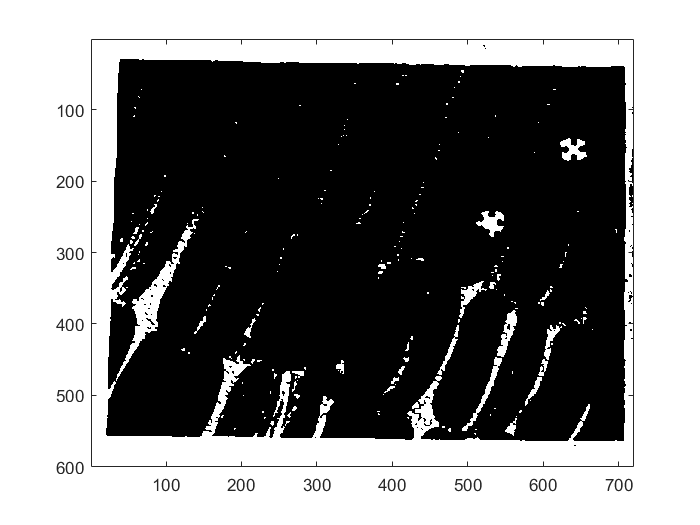

%Re-thresholding main image to help in image registration process
main = mainGray < 35;
imagesc(main);

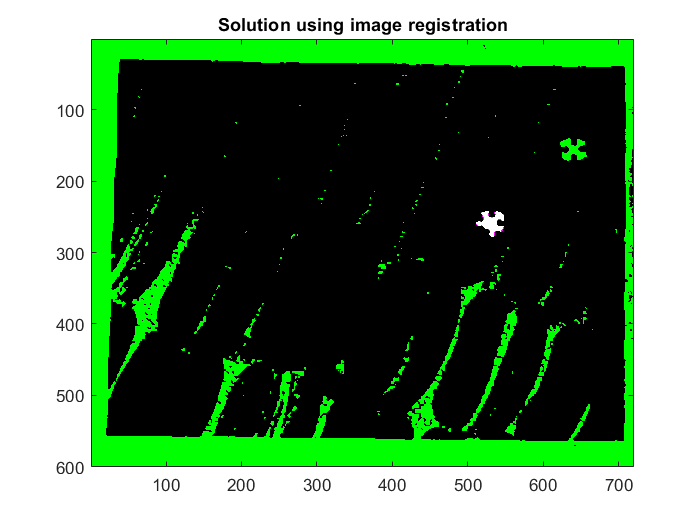

costmin = intmax;

%Calculating and storing all 8 rotations of the orange piece
allRotations = zeros(size(orangePiece,1),size(orangePiece,2),8);
allRotations(:,:,1) = orangePiece;

%Ignoring rotation of degree 0 as it will be same as the original piece 
for rot=2:no_of_rotations
    angle = (rot-1)*45;
    allRotations(:,:,rot) = rotatePiece(orangePiece,angle);
end

%Initialize frame to the top left corner of main
rowStartConst = 1;
rowEndConst = size(orangePiece,1)-1;
colStartConst = 1;
colEndConst = size(orangePiece,2)-1;

%Calculating the total orange piece intensity to help in optimizing the grid search
PieceIntensity = sum(orangePiece(:));

%Translating 1 pixel unit at a time
for shiftRow=0:size(main,1)
    rowStart = rowStartConst + shiftRow;
    rowEnd = rowEndConst + rowStart;
    colEnd = size(orangePiece,2)-1;
    
    if (rowStart > 0) && (rowEnd <= size(main,1))
        for shiftCol=0:size(main,2)
            colStart = colStartConst + shiftCol;
            colEnd = colEndConst + colStart;
            if (colStart > 0) && (colEnd <= size(main,2))
                
                frame = main(rowStart:rowEnd,colStart:colEnd);
                frameIntensity = sum(frame(:));
                
                %Ignoring frames which have either <=80% or >=120% of the total piece intensity,
                %Considering +/- 20% for noise data - Playing safe.
                %Reduces the execution time to ~7seconds from ~15seconds
                if(frameIntensity<0.8*PieceIntensity || frameIntensity>1.2*PieceIntensity)
                    continue;
                end
                
                %Find cost using least square
                costmat = (allRotations - frame).^2;
                cost = sum(sum(costmat));
                
                %Calculating minimum among all 8 rotations and then
                %comparing it with the current minimum to help speed up the process
                [Mini,Index] = min(cost);
                if(Mini<costmin)
                    costmin = Mini;
                    rowStartSol = rowStart;
                    rowEndSol = rowEnd;
                    colStartSol = colStart;
                    colEndSol = colEnd;
                    rotSol = Index;
                end
                
            else
                break;
            end
            
        end
    else
        break;
    end
    
end

%Generating the shape at the recognized match location with matched rotation
generated_image = zeros(size(main));
generated_image(rowStartSol:rowEndSol,colStartSol:colEndSol) = allRotations(:,:,rotSol);

%Combining the preprocessed main image with the generated shape
fused_img = imfuse(main, generated_image);
figure
imagesc(fused_img);
title('Solution using image registration');

%Function to rotate the R-Table


function new_table = rotatePhi(table,rot)
for k=1:length(table)
    temp = table(k).phi + rot*45;
    %Getting the angles of back into the interval -> -180 to +180 (Because of atan2)
    if(temp>180)
        x = mod(temp,360);
        if(x>180)
            x = -180 + mod(x,180);
        end
        temp = x;
    end
    table(k).phi = temp;
    
    %Rotating alpha
    table(k).alpha = table(k).alpha + rot*45;
end
new_table = table;
end


%Function to rotate the puzzle piece
function rotimg = rotatePiece(piece,angle)
%Creating a rot matrix
rotimg=zeros(size(piece));
rotmat=zeros(2,2);
rotmat(1,1)=cos(angle*pi/180);
rotmat(1,2)=-sin(angle*pi/180);
rotmat(2,1)=sin(angle*pi/180);
rotmat(2,2)=cos(angle*pi/180);
rotmat_inv=inv(rotmat);

%Using shift to preserving the whole orange piece after rotation
shift=zeros(2,1);
shift(1,1)= floor(size(piece,1)/2);
shift(2,1)= floor(size(piece,2)/2);
rho=0;

for i=1:size(piece,1)
    for j=1:size(piece,2)
        newpix(1,1)=i;
        newpix(2,1)=j;
       	oldpix=round(rotmat_inv*(newpix-shift)+shift);
        if (oldpix(1,1) > 0) && (oldpix(1,1) < size(piece,1)) && (oldpix(2,1) > 0) && (oldpix(2,1) < size(piece,2))
            rho=piece(oldpix(1,1),oldpix(2,1));
        end
       	rotimg(i,j)=rho;
    end
end
end